**Př. 3.: **Vygenerujte 10000 čísel z normálního rozdělení s parametry mi = 5, sigma^2 = 4 a vyneste je do grafu ve formě histogramu o 100 sloupcích. Do druhého obdobného grafu vyneste vygenerovaných 10000 čísel z normálního rozdělení s parametry mi = -5, sigma^2 = 4

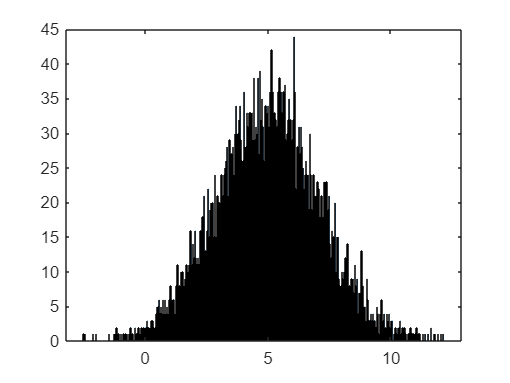

histogram(normrnd(5, 2, [1,10000]), 1000)

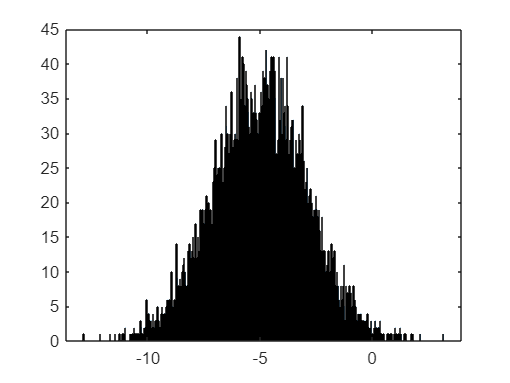

histogram(normrnd(-5, 2, [1,10000]), 1000)

**Př. 4: **Náhodná veličina A má E(X)=5 a D(X)=4, náhodná veličina B má E(X)=3 a D(X)=6, náhodná veličina C má E(X)=2 a D(X)=8. (Jsou nezávislé.) Vypočtěte střední hodnotu a rozptyl výsledné náhodné veličiny X, která je dána vzorcem X=A+B+C a Y=A+B-C**.**

E_X = 5 + 3 + 2
D_X = 4 + 6 + 8

**Př. 6.: **Náhodná veličina A má E(X)=5 a D(X)=4, náhodná veličina B má E(X)=0 a D(X)=16. Vypočtěte střední hodnotu a rozptyl výsledné náhodné veličiny X, která je dána vzorcem X=A+3*B.

E_X = 5 + 0
D_X = 4 + (3^2)*16 % Tbh nevim, proč ta trojka musí být na druhou

**Př. 7.:** Máte vygenerováno 1000 náhodných čísel z rovnoměrného rozdělení <0,1>. Určete pravděpodobnost, že průměr všech vygenerovaných čísel bude vyšší než 0.520.

E_X = (0 + 1) / 2 % Střední hodnota

E_X = 0.5000

D_X = (0 - 1)^2 / 12 % Rozptyl

D_X = 0.0833

n = 1000 % průměr

n = 1000


% N(E_X, D_X * 1 / n)
normcdf(1 - 0.52, E_X, sqrt(D_X * 1 / n))

ans = 0.0142

**Př. 9.: **Zatížení letadla s 64 místy nemá překročit 6000 kg. Jaká je pravděpodobnost, že při plném obsazení bude tato hodnota překročena, má-li hmotnost cestujícího střední hodnotu 90 kg a směrodatnou odchylku 10 kg.

E_X = 90

E_X = 90

D_X = 10^2

D_X = 100

n = 64 % součet

n = 64


1 - normcdf(6000, n * E_X, sqrt(n * D_X))

ans = 0.0013

**Př. 10.:** Počet chyb na jedné straně textu má střední hodnotu 3 a rozptyl 4. Jaká je pravděpodobnost, že na 400 stranách bude méně než 1000 chyb.

E_X = 3

E_X = 3

D_X = 4

D_X = 4

n = 400

n = 400


normcdf(1000, n * E_X, sqrt(n * D_X))

ans = 2.8665e-07

**Př. 11.: **Stokrát hodíme šestistěnnou kostkou. Jaká je pravděpodobnost, že součet hodů bude mezi 320 a 380.

n = 100

n = 100

E_X = 1/6 + 2/6 + 3/6 + 4/6 + 5/6 + 1

E_X = 3.5000

D_X = (1 - 3.5)^2 / 6 + (2 - 3.5)^2 / 6 + (3 - 3.5)^2 / 6 + (4 - 3.5)^2 / 6 + (5 - 3.5)^2 / 6 + (6 - 3.5)^2 / 6

D_X = 2.9167


normcdf(380.5, n * E_X, sqrt(n * D_X)) - normcdf(319.5, n * E_X, sqrt(n * D_X))

ans = 0.9259

**Př. 13.:** V osudí je 16 bílých a 14 černých koulí. Jaká je pravděpodobnost, že při 150 tazích jedné koule (s vracením) vytáhneme bílou právě 77x.

a) Řešte pomocí binomického rozdělení.

b) Řešte pomocí Poissonova rozdělení.

c) Řešte pomocí centrální limitní věty.

binopdf(77, 150, 16/30)

ans = 0.0577

poisspdf(77, 16/30 * 150)

ans = 0.0429


n = 150

n = 150

E_X = 16/30

E_X = 0.5333

D_X = 0 %???

D_X = 0


normcdf(77, n * E_X, sqrt(n * D_X))

ans = 0

**Př. 25.:** Určete pravděpodobnost, že Studentovo rozdělení s 2, 4, 10, 100 stupni volnosti nabývá P(X>1). Určete pravděpodobnost, i pro normované normální rozdělení

1 - tcdf(1, 2)

ans = 0.2113

1 - tcdf(1, 4)

ans = 0.1870

1 - tcdf(1, 10)

ans = 0.1704

1 - tcdf(1, 100)

ans = 0.1599

ans = -1.8125

ans = 1.8125

**Př. 26.: **Zjistěte 5% a 95% kvantil Studentova rozdělení s 10 stupni volnosti.

tinv(0.05, 10)
tinv(0.95, 10)

**Př. 28.: **Zjistěte 5% a 95% kvantil F rozdělení s 10 a 5 stupni volnosti. Dále určete 5% a 95% kvantil s 5 a 10 stupni volnosti. Zkuste odhadnout jaký je mezi výsledky vztah.

finv(0.05, 10, 5)

ans = 0.3007

finv(0.95, 10, 5)

ans = 4.7351

finv(0.05, 5, 10)

ans = 0.2112

finv(0.95, 5, 10)

ans = 3.3258